%% plot monte carlo for 12x4 (trail 1)
% plot ideal line
file_path = "dac_simulation_ideal.txt"

file_path = "dac_simulation_ideal.txt"

file = fopen(file_path, 'r');

ideal_current_list = [];
while ~feof(file)
    i = i + 1;
    line = fgetl(file);
    line = strtrim(line);
    if numel(line) >= 15 && i>1
            result_char = line(end-15:end);
            disp(result_char);
            result_current = str2double(result_char);
            ideal_current_list(end + 1) = result_current; 
    end
end 

        i(viout)
  1.23439037e-09
  5.67584166e-08
  6.79345860e-08
  9.79471793e-08
  9.02347779e-08
  1.28120924e-07
  1.30225793e-07
  1.49252003e-07
  1.34620279e-07
  1.74213042e-07
  1.80832906e-07
  2.02349895e-07
  1.94341041e-07
  2.22815792e-07
  2.22709481e-07
  2.36545382e-07
  2.22471726e-07
  2.58795531e-07
  2.67480466e-07
  2.88251542e-07
  2.84993618e-07
  3.10987708e-07
  3.14082158e-07
  3.28130810e-07
  3.20587205e-07
  3.47961809e-07
  3.54173707e-07
  3.70055574e-07
  3.66954410e-07
  3.87394536e-07
  3.89506525e-07
  4.00628764e-07
  3.94034053e-07
  4.21067291e-07
  4.30497927e-07
  4.47290546e-07
  4.49393191e-07
  4.69000433e-07
  4.74935156e-07
  4.87220277e-07
  4.87313251e-07
  5.06856694e-07
  5.14622521e-07
  5.27501705e-07
  5.30486787e-07
  5.45478755e-07
  5.51278433e-07
  5.61483297e-07
  5.63606854e-07
  5.80200734e-07
  5.88900292e-07
  6.00712369e-07
  6.06489039e-07
  6.19255012e-07
  6.26729992e-07
  6.36569816e-07
  6.42440767e-07
  6.54532158e-

fclose(file);
ideal_current_list = ideal_current_list(2:end)

ideal_current_list = 	1.0e+-5 *

    0.0001    0.0057    0.0068    0.0098    0.0090    0.0128    0.0130    0.0149    0.0135    0.0174    0.0181    0.0202    0.0194    0.0223    0.0223    0.0237    0.0222    0.0259    0.0267    0.0288    0.0285    0.0311    0.0314    0.0328    0.0321    0.0348    0.0354    0.0370    0.0367    0.0387    0.0390    0.0401    0.0394    0.0421    0.0430    0.0447    0.0449    0.0469    0.0475    0.0487    0.0487    0.0507    0.0515    0.0528    0.0530    0.0545    0.0551    0.0561    0.0564    0.0580


plot([1:128],1000000*ideal_current_list,"b-","LineWidth",2)
hold on

% plot 30 MC runs
difference = [];
for batch=1:3
for run= 1:10
file_path = sprintf('simulation_mc_%d_%d.txt', batch, run);
i = 0;
current_list = [];
file = fopen(file_path, 'r');

while ~feof(file)
    i = i + 1;
    line = fgetl(file);
    line = strtrim(line);
    if numel(line) >= 15 && i>1
            result_char = line(end-15:end);
            disp(result_char);
            result_current = str2double(result_char);
            current_list(end + 1) = result_current; 
    end
end

fclose(file);
plot([1:128],1000000*current_list,".-")
ylabel("current(uA)")
xlabel("bit value")
hold on

difference(batch*run, :) = current_list - ideal_current_list;
end
end 

  3.71029714e-08
  1.89972496e-07
  2.01062690e-07
  2.73882115e-07
  2.23408236e-07
  3.23955547e-07
  3.05675798e-07
  3.44544453e-07
  2.67730776e-07
  3.79010139e-07
  3.75566088e-07
  4.25185853e-07
  3.68616938e-07
  4.44758896e-07
  4.15933606e-07
  4.38914832e-07
  3.53902337e-07
  4.64985639e-07
  4.68418001e-07
  5.20412542e-07
  4.75486438e-07
  5.50540463e-07
  5.31003160e-07
  5.57613689e-07
  4.89744828e-07
  5.76176234e-07
  5.68497398e-07
  6.05247820e-07
  5.52641737e-07
  6.12439486e-07
  5.82912378e-07
  5.97806668e-07
  5.18293689e-07
  6.18748032e-07
  6.25078449e-07
  6.73205392e-07
  6.37911370e-07
  7.05250649e-07
  6.91753691e-07
  7.17383500e-07
  6.63600559e-07
  7.39163127e-07
  7.35821899e-07
  7.69314546e-07
  7.29015461e-07
  7.81163969e-07
  7.60077157e-07
  7.75254819e-07
  7.14510172e-07
  7.91773637e-07
  7.93294767e-07
  8.29323454e-07
  7.96475106e-07
  8.49174377e-07
  8.34374617e-07
  8.52649976e-07
  8.02913625e-07
  8.64414815e-07
  8.58054733e-

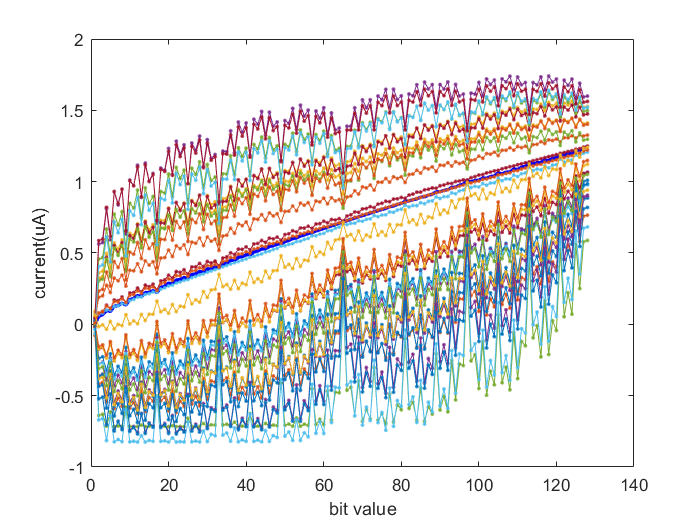


hold off 

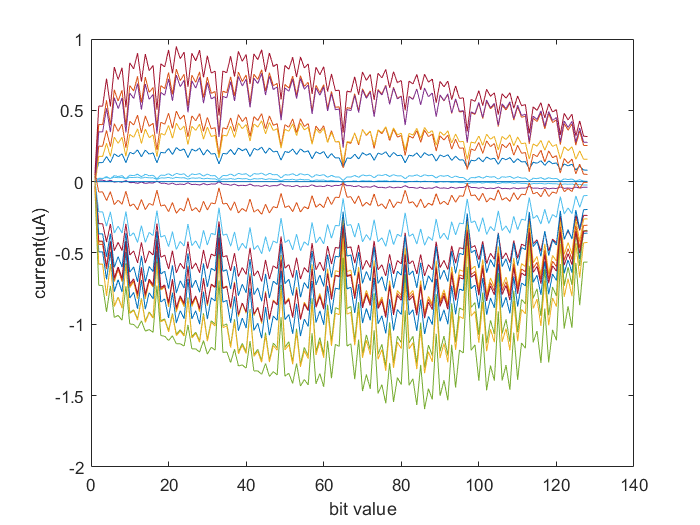

figure
plot([1:128],1000000*difference)
ylabel("current(uA)")
xlabel("bit value")